## Read Dataset

- total.csv : carbon emissions info for selected countries, total emissions for years 1750-2023, flat data from Global Carbon Project

- population.csv : population of selected, 1950-2023

total = readtable("total.csv")

total = 60828×12 table
        Country        ISO3166_1Alpha_3    UNM49    Year    Total    Coal    Oil    Gas    Cement    Flaring    Other    PerCapita
    _______________    ________________    _____    ____    _____    ____    ___    ___    ______    _______    _____    _________

    {'Afghanistan'}        {'AFG'}           4      1750     NaN     NaN     NaN    NaN      0         NaN       NaN        NaN   
    {'Afghanistan'}        {'AFG'}           4      1751     NaN     NaN     NaN    NaN      0         NaN       NaN        NaN   
    {'Afghanistan'}        {'AFG'}          

population = readtable('population.csv'); 

% Filter for selected countries
countries_ISO = {'BRA', 'CAN', 'CHN', 'FRA', 'ITA', 'IND', 'JPN', 'MEX', 'USA', 'GBR'};

total = total(ismember(total.ISO3166_1Alpha_3, countries_ISO), :);
population = population(ismember(population.ISO3, countries_ISO), :);

% Individal country carbon emission datasets
bra = total(string(total.ISO3166_1Alpha_3) == 'BRA', :);
can = total(string(total.ISO3166_1Alpha_3) == 'CAN', :);
chn = total(string(total.ISO3166_1Alpha_3) == 'CHN', :);
fra = total(string(total.ISO3166_1Alpha_3) == 'FRA', :);
ita = total(string(total.ISO3166_1Alpha_3) == 'ITA', :);
ind = total(string(total.ISO3166_1Alpha_3) == 'IND', :);
jpn = total(string(total.ISO3166_1Alpha_3) == 'JPN', :);
mex = total(string(total.ISO3166_1Alpha_3) == 'MEX', :);
usa = total(string(total.ISO3166_1Alpha_3) == 'USA', :);
gbr = total(string(total.ISO3166_1Alpha_3) == 'GBR', :);

% Individal country population datasets
bra_p = population(string(population.ISO3) == 'BRA', :);
can_p = population(string(population.ISO3) == 'CAN', :);
chn_p = population(string(population.ISO3) == 'CHN', :);
fra_p = population(string(population.ISO3) == 'FRA', :);
ita_p = population(string(population.ISO3) == 'ITA', :);
ind_p = population(string(population.ISO3) == 'IND', :);
jpn_p = population(string(population.ISO3) == 'JPN', :);
mex_p = population(string(population.ISO3) == 'MEX', :);
usa_p = population(string(population.ISO3) == 'USA', :);
gbr_p = population(string(population.ISO3) == 'GBR', :);

usa

usa = 274×12 table
    Country    ISO3166_1Alpha_3    UNM49    Year    Total    Coal    Oil    Gas    Cement    Flaring    Other    PerCapita
    _______    ________________    _____    ____    _____    ____    ___    ___    ______    _______    _____    _________

    {'USA'}        {'USA'}          840     1750     NaN     NaN     NaN    NaN     NaN        NaN       NaN        NaN   
    {'USA'}        {'USA'}          840     1751     NaN     NaN     NaN    NaN     NaN        NaN       NaN        NaN   
    {'USA'}        {'USA'}          840     1752     NaN     NaN     NaN    NaN 

usa_p

usa_p = 204×5 table
    CountryName     ISO3      UNcode    Year    Population
    ___________    _______    ______    ____    __________

      {'USA'}      {'USA'}     840      1820    9.9805e+06
      {'USA'}      {'USA'}     840      1821    1.0299e+07
      {'USA'}      {'USA'}     840      1822    1.0626e+07
      {'USA'}      {'USA'}     840      1823    1.0951e+07
      {'USA'}      {'USA'}     840      1824    1.1277e+07
      {'USA'}      {'USA'}     840      1825    1.1602e+07
      {'USA'}      {'USA'}     840      1826    1.1928e+07
      {'USA'}      {'USA'}     840      1827    1.2251e+07
      {'USA'}      {'USA'}     840      1828    1.2581e+07
      {'USA'}      {'USA'}     840      1829    1.2906e+07
      {'USA'}      {'USA'}     840      1830     1.324e+07
      {'USA'}      {'USA'}     840      18

## Clean and Prepare Data (USA)

### Remove NaN values from dataset

- No missing values from 1800-2023

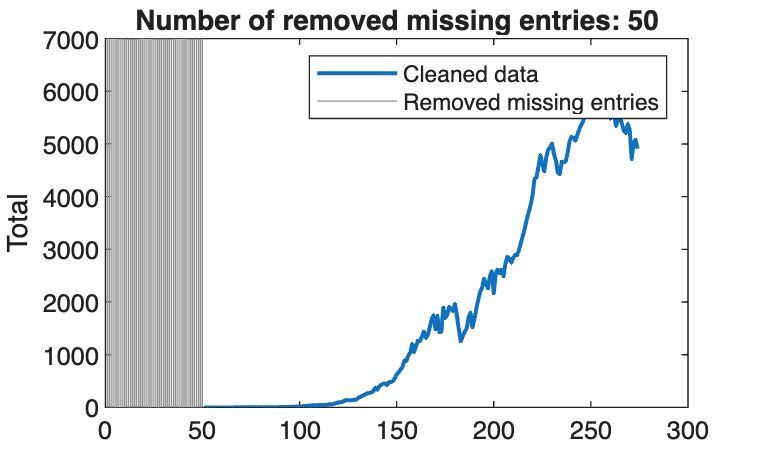

% Remove missing data
[usa,missingIndices] = rmmissing(usa,DataVariables="Total");

% Display results
figure

% Plot cleaned data
plot(find(~missingIndices),usa.Total,SeriesIndex=1,LineWidth=1.5, ...
    DisplayName="Cleaned data")
hold on

% Plot removed missing entries
x = repelem(find(missingIndices),3);
y = repmat([ylim(gca) missing]',nnz(missingIndices),1);
plot(x,y,"Color",[145 145 145]/255,DisplayName="Removed missing entries")
title("Number of removed missing entries: " + nnz(missingIndices))

hold off
legend
ylabel("Total")

clear x y
usa

usa = 224×12 table
    Country    ISO3166_1Alpha_3    UNM49    Year     Total      Coal      Oil    Gas    Cement    Flaring    Other    PerCapita
    _______    ________________    _____    ____    _______    _______    ___    ___    ______    _______    _____    _________

    {'USA'}        {'USA'}          840     1800    0.25282    0.25282     0      0       0         NaN       NaN     0.042136 
    {'USA'}        {'USA'}          840     1801    0.26747    0.26747     0      0       0         NaN       NaN     0.043749 
    {'USA'}        {'USA'}          840     1802    0.28946 

## Split data into training and test sets

- usaTrain : training set 1800-2018

- usaTest : test set 2019-2023

Major changes in carbon emissions after Kyoto Agreement (1997) and Paris Agreement (2015)

- Predicting for 5 years (test set)

- Split by index

% Training and test indices
n = height(usa);
train_size = floor(0.98 * n);

trainIdx = false(n, 1);
testIdx = false(n, 1);

trainIdx(1:train_size) = true;
testIdx(train_size+1:end) = true;

% Create training and test sets
usaTrain = usa(trainIdx, :);
usaTest = usa(testIdx, :);


disp(['Training set size: ', num2str(sum(trainIdx))]);

Training set size: 219


disp(['Test set size: ', num2str(sum(testIdx))]);

Test set size: 5


## Make data stationary

Stationary data is crucial for time-series models

Reduce variance by **transforming data, removing trends, and performing data decomposition**

### Visualize current dataset (USA)

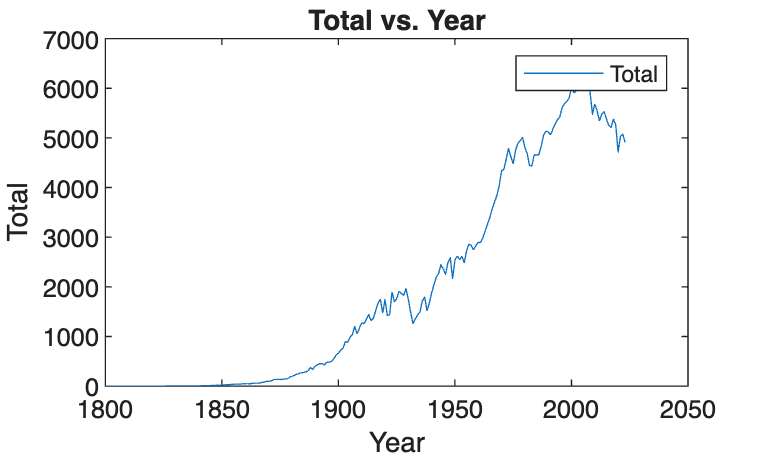

% Create plot of usa.Year and usa.Total
usaTotalYear = plot(usa,"Year","Total","DisplayName","Total");

% Add xlabel, ylabel, title, and legend
xlabel("Year")
ylabel("Total")
title("Total vs. Year")
legend

From this plot, we see that the data follows a generally exponential trend, thus we take the log to make the data more stationary.

### Transform Data

Take log of Total

usaTrain.log = log(usaTrain.Total);

% Visualize Transformation

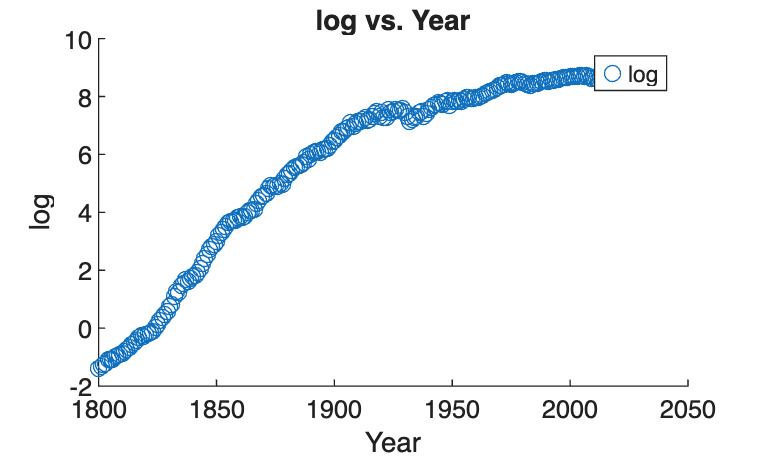

% Create scatter of usaTrain.Year and usaTrain.log
usaTrainTotalLog = scatter(usaTrain,"Year","log","DisplayName","log");

% Add xlabel, ylabel, title, and legend
xlabel("Year")
ylabel("log")
title("log vs. Year")
legend

### Remove Trends

Remove quadratic or **cubic** trend so that model can have flexibility

- Initial attempts with removing linear trend yielded modes that could not accurately fit to dataset

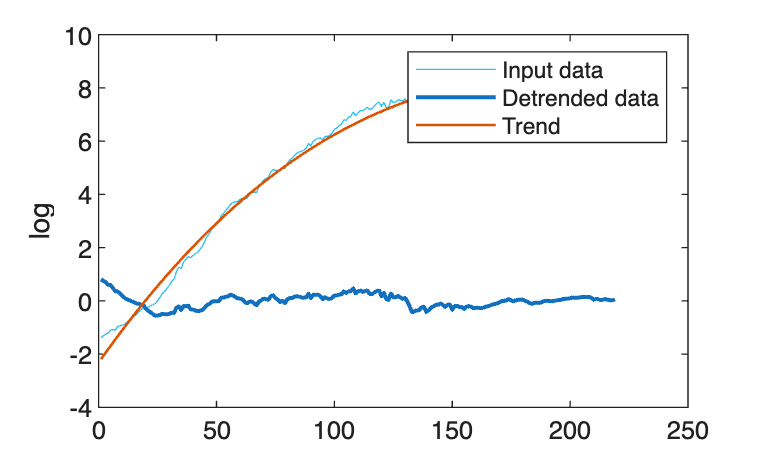

% Remove trend from input data
cubicTrend = detrend(usaTrain,3,DataVariables="log");

% Display results
figure
plot(usaTrain.log,SeriesIndex=6,DisplayName="Input data")
hold on
plot(cubicTrend.log,SeriesIndex=1,LineWidth=1.5,DisplayName="Detrended data")
plot(usaTrain.log-cubicTrend.log,SeriesIndex=2,LineWidth=1,DisplayName="Trend")
hold off
legend
ylabel("log")


% Save detrended data
usaTrain.cubeDetrended = usaTrain.log - cubicTrend.log

usaTrain = 219×14 table
    Country    ISO3166_1Alpha_3    UNM49    Year     Total      Coal      Oil    Gas    Cement    Flaring    Other    PerCapita      log       cubeDetrended
    _______    ________________    _____    ____    _______    _______    ___    ___    ______    _______    _____    _________    ________    _____________

    {'USA'}        {'USA'}          840     1800    0.25282    0.25282     0      0       0         NaN       NaN     0.042136      -1.3751       -2.1888   
    {'USA'}        {'USA'}  

### Perform data decomposition

Decompose data into Long Term, Seasonal, and Remainder components, which will then be individually modeled on

% Decompose data into long-term trend, seasonal trends, and remainder
trends = trenddecomp(usaTrain(:,"cubeDetrended"),"ssa",109,NumSeasonal=1);

% Display results
figure
stackedplot([usaTrain(:,14) trends],"DisplayLabels",["Input data","Long-term", ...
    "Periodic","Remainder"]);

allComponents = table;
allComponents.CubeComp = cubicTrend.log;
allComponents.LongTermComp = trends.cubeDetrended_LongTerm;
allComponents.SeasComp = trends.cubeDetrended_Seasonal;
allComponents.Year = usaTrain.Year;

remainingTS = table;
remainingTS.Year = usaTrain.Year

remainingTS = 219×1 table
    Year
    ____

    1800
    1801
    1802
    1803
    1804
    1805
    1806
    1807
    1808
    1809
    1810
    1811
    1812
    1813
    1814
    1815


remainingTS.Remainder = round(trends.cubeDetrended_Remainder,4)

remainingTS = 219×2 table
    Year    Remainder
    ____    _________

    1800     -0.0041 
    1801     -0.0038 
    1802     -0.0035 
    1803     -0.0033 
    1804      -0.003 
    1805     -0.0028 
    1806     -0.0025 
    1807     -0.0023 
    1808     -0.0021 
    1809     -0.0019 
    1810     -0.0017 
    1811     -0.0015 
    1812     -0.0013 
    1813     -0.0012 
    1814      -0.001 
    1815     -0.0009 


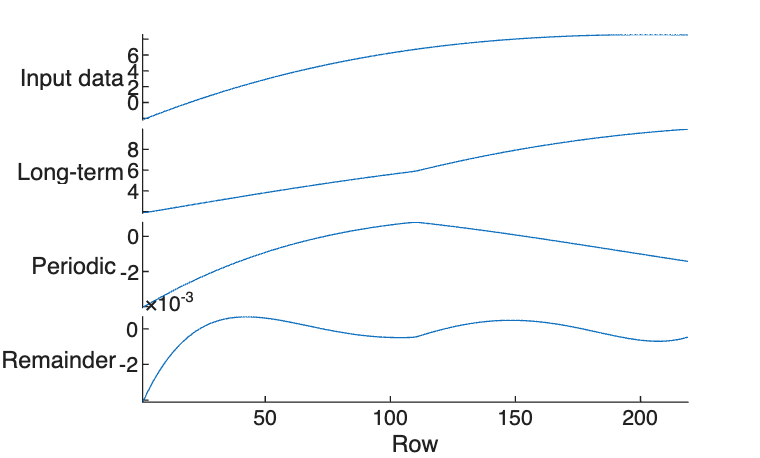


% Visualize decomposed components
tiledlayout(2,2)

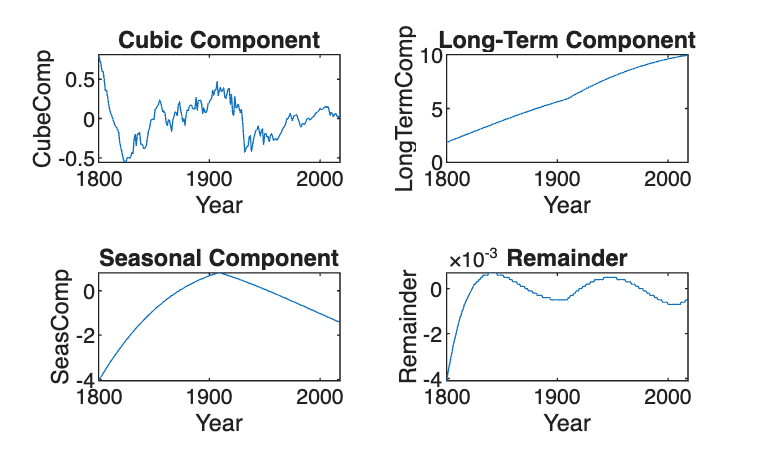

nexttile
plot(allComponents,"Year","CubeComp")
title("Cubic Component")

nexttile
plot(allComponents,"Year","LongTermComp")
title("Long-Term Component")

nexttile
plot(allComponents,"Year","SeasComp")
title("Seasonal Component")

nexttile
plot(remainingTS,"Year","Remainder")
title("Remainder")

## Model Individual Components - NOT USING ANYMORE

R^2: 0.72463

CubeMdl = createCubicFit(allComponents.CubeComp)

CubeMdl =      Linear model Poly5:
     CubeMdl(x) = p1*x^5 + p2*x^4 + p3*x^3 + p4*x^2 + p5*x + p6
     Coefficients (with 95% confidence bounds):
       p1 =  -2.402e-10  (-2.691e-10, -2.112e-10)
       p2 =   1.459e-07  (1.299e-07, 1.619e-07)
       p3 =  -3.194e-05  (-3.513e-05, -2.874e-05)
       p4 =    0.003002  (0.002724, 0.00328)
       p5 =     -0.1102  (-0.1201, -0.1003)
       p6 =      0.9889  (0.88, 1.098)

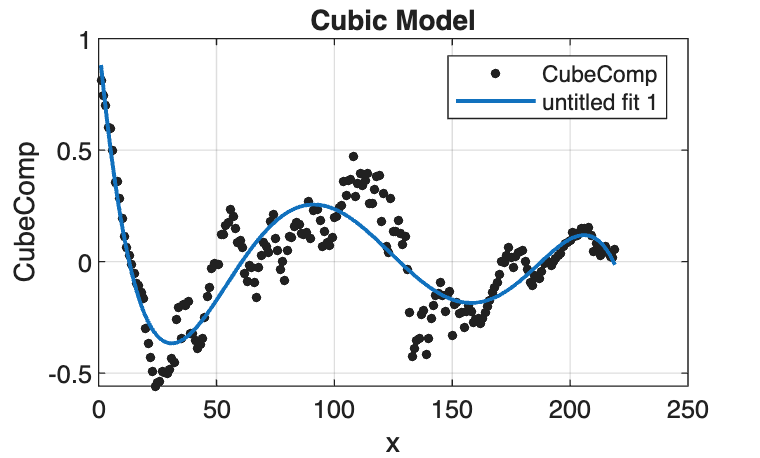

title("Cubic Model")

R^2: 0.99658

LongTermMdl = createLTFit(allComponents.LongTermComp)

LongTermMdl =      Linear model Poly1:
     LongTermMdl(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =     0.03907  (0.03876, 0.03938)
       p2 =       1.848  (1.809, 1.887)

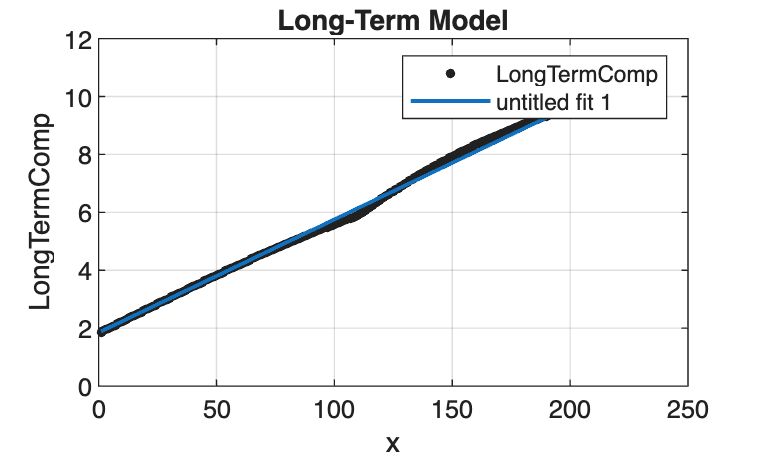

title("Long-Term Model")

R^2: 0.99772

SeasMdl = createSeasFit(allComponents.SeasComp)

SeasMdl =      General model Sin2:
     SeasMdl(x) =  a1*sin(b1*x+c1) + a2*sin(b2*x+c2)
     Coefficients (with 95% confidence bounds):
       a1 =       2.798  (-6.521, 12.12)
       b1 =     0.01761  (0.003292, 0.03193)
       c1 =       0.109  (-2.067, 2.285)
       a2 =        10.3  (-489.7, 510.3)
       b2 =    0.002302  (-0.1218, 0.1264)
       c2 =     -0.4342  (-23.71, 22.84)

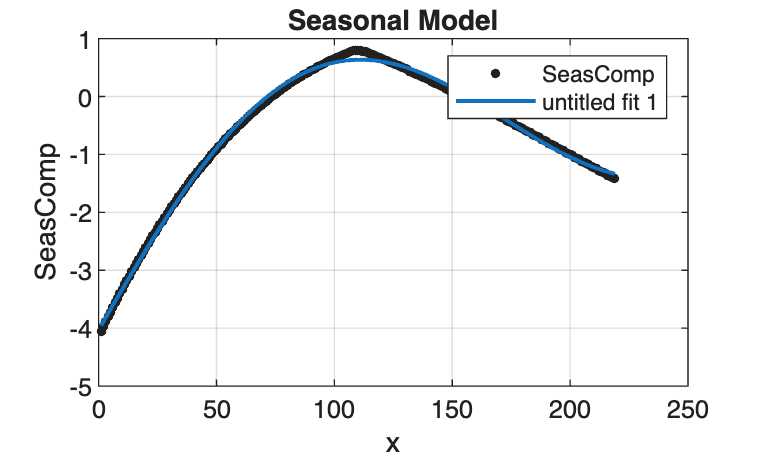

title("Seasonal Model")

### ACF and PACF of Remainder component (cubic detrended)

Utilize ACF and PACF plots to guide model selection

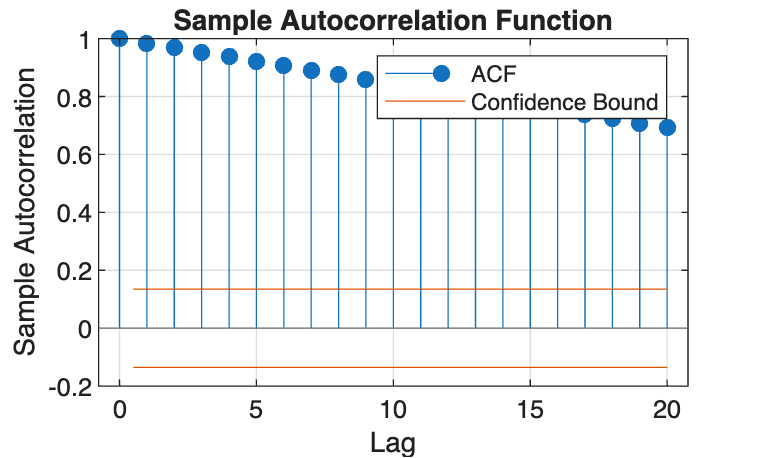

autocorr(usaTrain.cubeDetrended, NumLags=20)

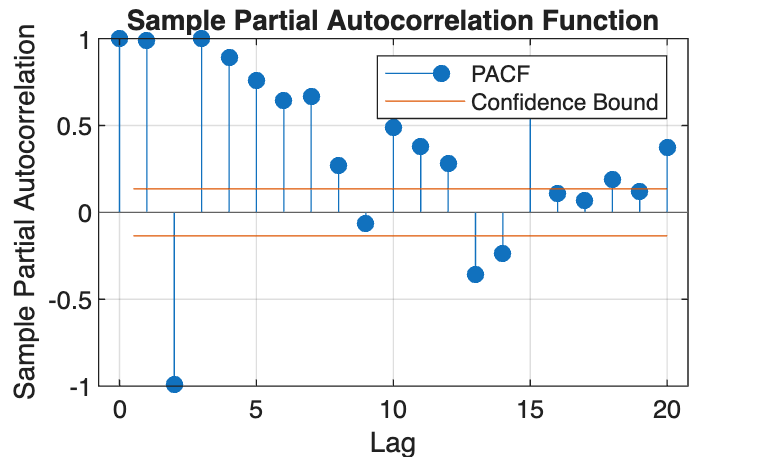

parcorr(usaTrain.cubeDetrended, NumLags=20)

ACF plot does not show seasonality, suggesting use of ARIMA Model.

## Model Selection and Forecasting

### Set up model components - NOT USING ANYMORE

frcst = table;
frcst.Year = usaTest.Year;

prevIdx = height(usaTrain)

prevIdx = 219

frcst.Idx = (prevIdx+1:prevIdx+height(frcst))'

frcst = 5×2 table
    Year    Idx
    ____    ___

    2019    220
    2020    221
    2021    222
    2022    223
    2023    224


frcstHorizon = height(frcst)

frcstHorizon = 5


[frcst.CubeFrcst, gof] = feval(CubeMdl, frcst.Idx);
frcst.LongTermFrcst = feval(LongTermMdl, frcst.Idx);
frcst.SeasFrcst = feval(SeasMdl, frcst.Idx)

frcst = 5×5 table
    Year    Idx    CubeFrcst    LongTermFrcst    SeasFrcst
    ____    ___    _________    _____________    _________

    2019    220    -0.038704       10.443         -1.3429 
    2020    221    -0.065578       10.482         -1.3518 
    2021    222    -0.095131       10.521           -1.36 
    2022    223     -0.12749        10.56         -1.3675 
    2023    224     -0.16277         10.6         -1.3744 


### Gridsearch for ARIMA Parameters p and q

p_range = 0:5;
q_range = 0:5;

% store model results
results = [];

% Grid search on residuals
for p = p_range
    for q = q_range
        try
            % Fit ARIMA model with d=0
            model = arima(p, 0, q);
            fit = estimate(model, usaTrain.cubeDetrended, 'Display', 'off');
            
            % Get log-likelihood
            [~, ~, logL] = infer(fit, usaTrain.cubeDetrended);
            
            numParams = p + q;
            if fit.Constant ~= 0 
                numParams = numParams + 1;
            end
            
            n = length(usaTrain.cubeDetrended);
            
            aic = -2*logL + 2*numParams;
            bic = -2*logL + numParams*log(n);
            
            % Store results: [p, q, AIC, BIC, LogLikelihood]
            results = [results; p, q, aic, bic, logL];
            
        catch ME
            fprintf('Failed to fit ARIMA(%d,0,%d): %s\n', p, q, ME.message);
            continue;
        end
    end
end

Failed to fit ARIMA(2,0,0): Estimated variance model is invalid.
Failed to fit ARIMA(2,0,2): Estimated variance model is invalid.
Failed to fit ARIMA(2,0,3): Estimated variance model is invalid.
Failed to fit ARIMA(2,0,4): Estimated variance model is invalid.
Failed to fit ARIMA(3,0,1): Estimated variance model is invalid.
Failed to fit ARIMA(3,0,2): Estimated variance model is invalid.
Failed to fit ARIMA(3,0,3): Estimated variance model is invalid.
Failed to fit ARIMA(4,0,2): Estimated variance model is invalid.
Failed to fit ARIMA(4,0,3): Estimated variance model is invalid.
Failed to fit ARIMA(4,0,5): Estimated variance model is invalid.
Failed to fit ARIMA(5,0,0): Estimated variance model is invalid.
Failed to fit ARIMA(5,0,1): Estimated variance model is invalid.
Failed to fit ARIMA(5,0,2): Estimated variance model is invalid.
Failed to fit ARIMA(5,0,3): Estimated variance model is invalid.


Failed to fit ARIMA(5,0,4): Estimated variance model is invalid.


Failed to fit ARIMA(5,0,5): Estimated variance model is invalid.



% Convert to table for easier viewing
resultsTable = array2table(results, ...
    'VariableNames', {'p', 'q', 'AIC', 'BIC', 'LogLikelihood'});

% Sort by AIC (lower is better)
resultsTable = sortrows(resultsTable, 'AIC');

% Display top 10 models
disp('Top 10 models by AIC:');

Top 10 models by AIC:


disp(resultsTable(1:min(10, height(resultsTable)), :));

    p    q      AIC        BIC      LogLikelihood
    _    _    _______    _______    _____________

    2    5    -2957.9    -2930.8         1487    
    3    5    -2954.3    -2923.8       1486.1    
    3    4    -2953.6    -2926.5       1484.8    
    4    4    -2937.9    -2907.4       1477.9    
    2    1    -2917.1    -2903.6       1462.6    
    3    0    -2766.2    -2752.6       1387.1    
    4    0    -2550.8    -2533.8       1280.4    
    4    1    -2516.9    -2496.5       1264.4    
    1    5    -1242.4    -1218.7       628.19    
    1    4    -1209.7    -1189.4       610.85    



### Find best models (AIC, BIC)

[~, idx_aic] = min(resultsTable.AIC);
[~, idx_bic] = min(resultsTable.BIC);

fprintf('\n=== BEST MODELS ===\n');


=== BEST MODELS ===


fprintf('Best by AIC: ARIMA(%d,0,%d) - AIC = %.4f\n', ...
    resultsTable.p(idx_aic), resultsTable.q(idx_aic), resultsTable.AIC(idx_aic));

Best by AIC: ARIMA(2,0,5) - AIC = -2957.9266


fprintf('Best by BIC: ARIMA(%d,0,%d) - BIC = %.4f\n', ...
    resultsTable.p(idx_bic), resultsTable.q(idx_bic), resultsTable.BIC(idx_bic));

Best by BIC: ARIMA(2,0,5) - BIC = -2930.8140



% Fit the best model (by BIC)
best_p = resultsTable.p(idx_bic);
best_q = resultsTable.q(idx_bic);

fprintf('\nFitting best model: ARIMA(%d,0,%d)...\n', best_p, best_q);


Fitting best model: ARIMA(2,0,5)...


bestModel = arima(best_p, 0, best_q);
bestARIMAfit = estimate(bestModel, usaTrain.cubeDetrended, 'Display', 'off');

% Display fitted model
disp(bestARIMAfit);

  arima with properties:

     Description: "ARIMA(2,0,5) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 2
               D: 0
               Q: 5
        Constant: -0.000634759
              AR: {1.99954 -0.999541} at lags [1 2]
             SAR: {}
              MA: {1.25593 1.08156 1 1 0.541876} at lags [1 2 3 4 5]
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 2e-07


## Model Forecast Predictions for next 5 years

frcst.ARIMABest = forecast(bestARIMAfit, frcstHorizon, usaTrain.cubeDetrended);

% Combining forcasts - NOT USED ANYMORE
frcst.Sum = frcst.CubeFrcst + frcst.LongTermFrcst + frcst.ARIMABest + frcst.SeasFrcst

frcst = 5×7 table
    Year    Idx    CubeFrcst    LongTermFrcst    SeasFrcst    ARIMABest     Sum  
    ____    ___    _________    _____________    _________    _________    ______

    2019    220    -0.038704       10.443         -1.3429      8.5298      17.591
    2020    221    -0.065578       10.482         -1.3518      8.5243      17.589
    2021    222    -0.095131       10.521           -1.36      8.5184      17.585
    2022    223     -0.12749        10.56         -1.3675      8.5119      17.577
    2023    224     -0.16277         10.6         -1.3744      8.5049      17.567


frcst.Co2Forecast = exp(frcst.Sum);        % untransform

% Untransform

frcst = 5×8 table
    Year    Idx    CubeFrcst    LongTermFrcst    SeasFrcst    ARIMABest     Sum      Co2Forecast
    ____    ___    _________    _____________    _________    _________    ______    ___________

    2019    220    -0.038704       10.443         -1.3429      8.5298      8.5298      5063.4   
    2020    221    -0.065578       10.482         -1.3518      8.5243      8.5243      5035.9   
    2021    222    -0.095131       10.521           -1.36      8.5184      8.5184      5006.1   
    2022    223     -0.12749        10.56         -1.3675      8.5119      8.5119      4973.8   
    2023    224     -0.16277         10.6         -1.3744      8.5049      8.5049      4938.7   


frcst.Co2Forecast = exp(frcst.ARIMABest); 


## Model Evaluation (RMSE)

% Calculate RMSE
%remove 2019 2020
E = rmse(frcst.Co2Forecast(3:5, :), usaTest.Total(3:5, :));

% Display the result
disp(['The RMSE is: ', num2str(E)]);

The RMSE is: 64.4912


% W/O INDEXING
% Calculate RMSE (w/o indexing/removing 2019 2020)
E = rmse(frcst.Co2Forecast, usaTest.Total);

% Display the result
disp(['The RMSE is: ', num2str(E)]);


### Plot results

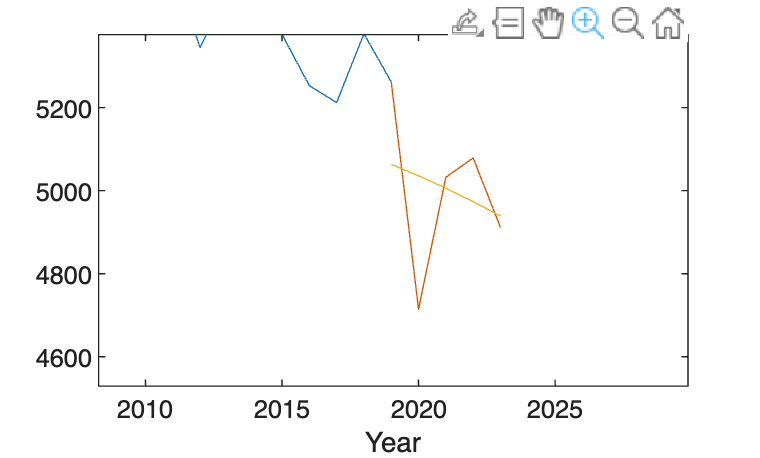

The RMSE is: 176.171


figure
plot(usa, "Year", "Total")

hold on
plot(usaTest, "Year", "Total")
hold on
plot(frcst,"Year","Co2Forecast")
hold off